clear all

t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 4

knots = 4

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.3*rand(timesteps,1));
output2= cos(5*t)+0.4*rand(timesteps,1)

output2 =     1.2623
    0.9832
    1.2172
    1.1053
    0.8118
    0.6184
    0.3680
   -0.0214
   -0.1540
   -0.5597



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.1266
   -1.2388
   -1.2623
   -1.1527
   -1.2623
   -0.8370
   -0.2217
   -0.0723
   -0.3698
   -0.4076


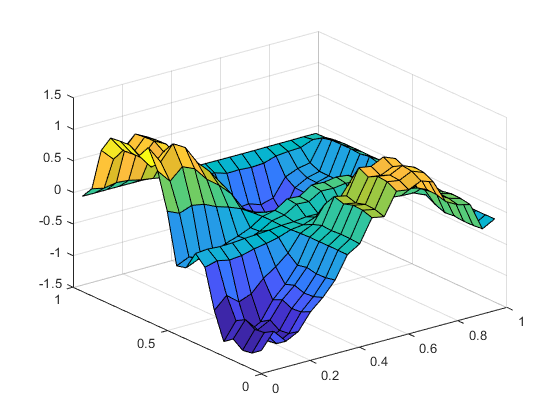


% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));
   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros(36,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye(36)*1000

Pcov =         1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0        1000           0           0           0           0           0           0           0       



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end
toc

Elapsed time is 0.087227 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:) ;
toc

Elapsed time is 0.045790 seconds.


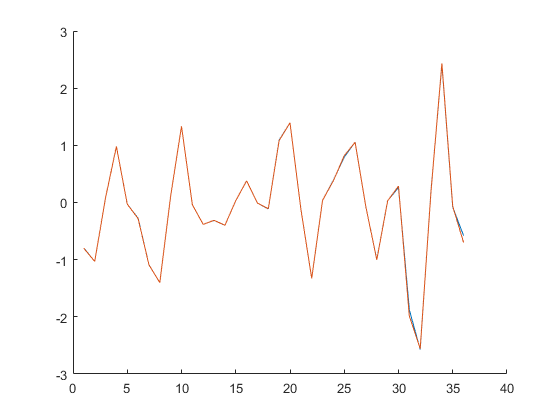


y=C*P;
y=C*Theta;

figure;
hold on
plot(Theta)
plot(P)
hold off

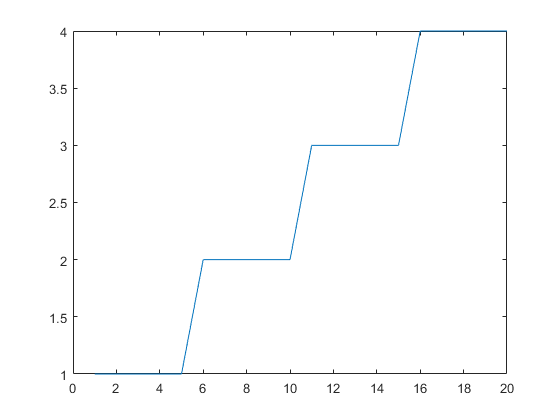


plot(index)

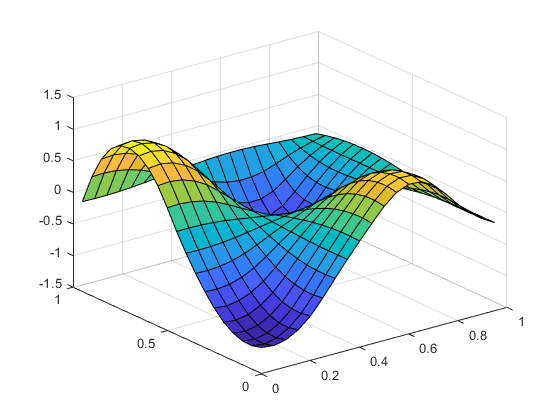

surf(t,t,reshape(y,[timesteps timesteps]))

surf(t,t,output_curve)

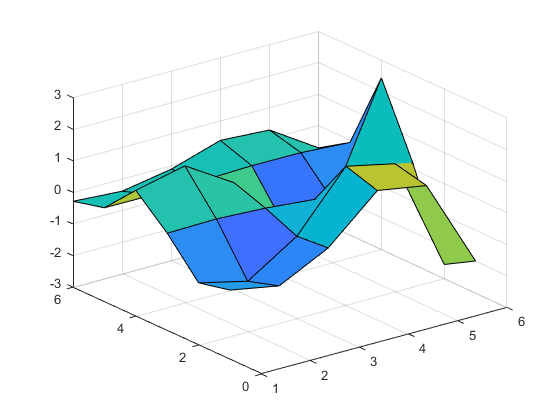


surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))


norm(reshape(y,[timesteps timesteps])-output_curve)

ans = 2.5098


% surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))



[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =     0.2884    0.9047   -0.2162    0.1966    0.0601
    0.3920   -0.3709   -0.4804    0.6553    0.1233
    0.1116    0.0431   -0.1751   -0.4548    0.6280
   -0.3900    0.0992    0.5061    0.5417    0.5330
   -0.2946    0.1745    0.0152    0.1780   -0.5368
    0.7154   -0.0422    0.6599    0.0012   -0.1203


score =    -2.1577    0.0000    0.0000   -0.0000    0.0000
   -2.9512   -0.0000    0.0000    0.0000   -0.0000
    0.9114   -0.0000   -0.0000   -0.0000   -0.0000
    4.0254    0.0000    0.0000    0.0000    0.0000
    0.5263   -0.0000    0.0000   -0.0000    0.0000
   -0.3542    0.0000   -0.0000    0.0000    0.0000


latent =     6.1604
    0.0000
    0.0000
    0.0000
    0.0000


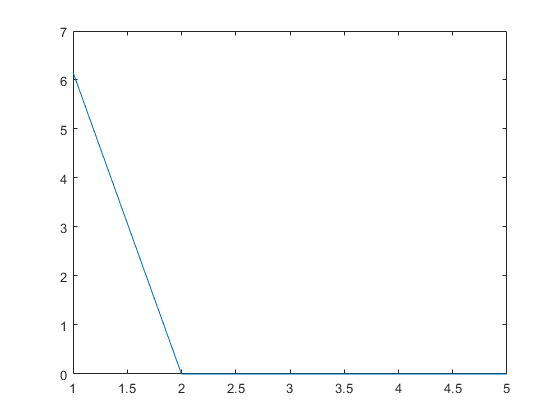


plot(latent)